# `Ex004 - Showcase of the available PES model curves that can be used for fitting`

This example shows all of the curve line-shapes that are available to use when fitting to either ARPES or XPS data obtained from the ADRESS beamline. 

- **For PES curves:** **Gaussian**, **Lorentzian**, **Voigt**, **asymmetrical Voigt **and **Doniach-Sunjic** functions are all available.

- The **Fermi-Dirac Distribution** **(FDD)** is also defined here, which can be also used for fitting states near the Fermi-edge.

close all; clear all;
pp = plot_props();

# **The functions below are used to create a general best-fit lineshape to PES data**

**(1) Generic, vanilla PES curve**

The function 'PESCurve()' can be used to call any curve line-shape that can be used to fit to PES data.  The option is here to also plot its spin-orbit split component, along with its energy shift and branching ratio. Using a linear combination of 'PESCurve()' outputs, we can then fit to any PES data.

help PESCurve;

  ydat = PESCurve(xdat, cTYPE, BE, INT, FWHM, MR, LSE, LSI, LSW, ASY, plot_result)
    Function that evaluates a generic photoelectron spectroscopy (PES)
    curve, by defining a primary (P) and spin-orbit split (SOS) component.
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:    	N×1 column vector of the input domain (binding energy for XPS)
    -   cTYPE:      type of curve to use for fitting. Default: "sGLA" ("sGLA", "pGLA", "sGL", "pGL", "G", "L", "DS")
    -   BE:      	scalar of the binding energy of PE curve.
    -   INT:    	scalar of the peak intensity of PE curve.
    -   FWHM:     	scalar of the FWHM of the PE curve.
    -   MR:     	scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
    -   LSE:     	scalar of the binding energy of spin-orbit split PE curve.
    -   LSI:     	scalar of the branching ratio of spin-orbit split PE curve.
    -   LSW:     	scalar of the additional lorentzian width of spin-orbit split PE curve.
    -   

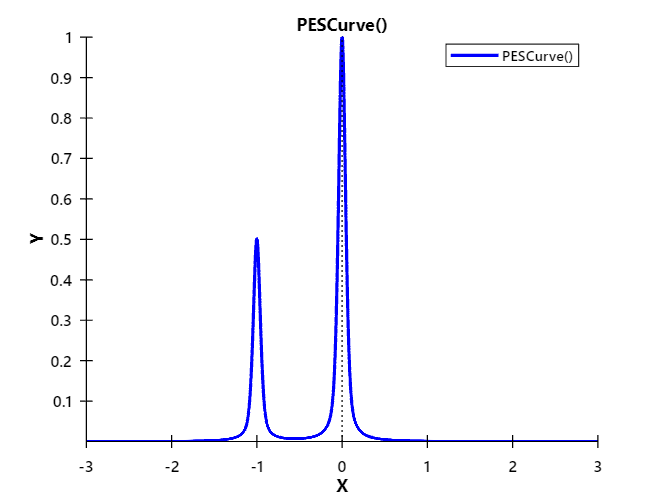

% 1 - Defining the input parameters
xdat = linspace(-3, 3, 1e4);
TYPE    = "sGLA";   % type of curve to use for fitting. Default: "sGLA" ("pGLA", "sGL", "pGL", "G", "L", "DS")
BE      =  0.0;      % scalar of the binding energy of PE curve.
INT     =  1.0;      % scalar of the peak intensity of PE curve.
FWHM    =  0.1;     % scalar of the FWHM of the PE curve.
MR      =  0.5;     % scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
LSE     = -1.0;     % scalar of the binding energy of spin-orbit split PE curve.
LSI     =  0.5;     % calar of the branching ratio of spin-orbit split PE curve.
LSW     =  0.0;     % scalar of the additional lorentzian width of spin-orbit split PE curve.
ASY     =  0.;     % scalar of the PE curve asymmetry parameter (usually for metallic systems).
% 2 - Calculating the lineshape
ydat    = PESCurve(xdat, TYPE, BE, INT, FWHM, MR, LSE, LSI, LSW, ASY, 1);

**(2) PES curve convolved with a Fermi-Dirac Distribution (FDD) for near Fermi-edge fitting problems**

The function 'PESCurve_FDD()' can be used to call a generic curve line-shape that has been convolved with an FDD. This is useful for near Fermi-edge fitting problems.

help PESCurve_FDD;

  ydat = PESCurve_FDD(xdat, cTYPE, BE, INT, FWHM, MR, LSE, LSI, LSW, ASY, FDEF, FDT, FDW, plot_result)
    Function that evaluates a generic photoelectron spectroscopy (PES)
    curve, by defining a primary (P) and spin-orbit split (SOS) component.
    A Fermi-Dirac Distribution (FDD) is also multiplied with the PES curve.
    This type of curve should be used to fit near Fermi-edge EDC cuts.
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:       N×1 column vector of the input domain (binding energy for PES).
    -   cTYPE:      type of curve to use for fitting. Default: "sGLA" ("sGLA", "pGLA", "sGL", "pGL", "G", "L", "DS")
    -   BE:      	scalar of the binding energy of PE curve.
    -   INT:    	scalar of the peak intensity of PE curve.
    -   FWHM:     	scalar of the FWHM of the PE curve.
    -   MR:     	scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
    -   LSE:     	scalar of the binding energy of spin-orbit split PE curve.
    - 

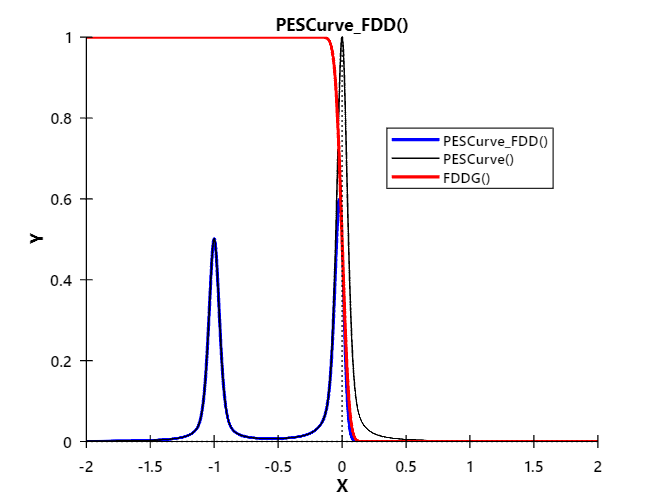

% 1 - Defining the input parameters
xdat = linspace(-2, 2, 1e4);
TYPE    = "sGLA";   % type of curve to use for fitting. Default: "sGLA" ("pGLA", "sGL", "pGL", "G", "L", "DS")
BE      =  0.0;     % scalar of the binding energy of PE curve.
INT     =  1.0;     % scalar of the peak intensity of PE curve.
FWHM    =  0.1;     % scalar of the FWHM of the PE curve.
MR      =  0.5;     % scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
LSE     = -1.0;     % scalar of the binding energy of spin-orbit split PE curve.
LSI     =  0.5;     % calar of the branching ratio of spin-orbit split PE curve.
LSW     =  0.0;     % scalar of the additional lorentzian width of spin-orbit split PE curve.
ASY     =  0.0;     % scalar of the PE curve asymmetry parameter (usually for metallic systems).
FDEF    =  0.0;     % scalar of the FDD Fermi-Level position.
FDT     =  12.0;    % scalar of the FDD temperature.
FDW     =  0.10;    % scalar of the FDD Gaussian width after convolution.
% 2 - Calculating the lineshape
ydat_01     = PESCurve_FDD(xdat, TYPE, BE, INT, FWHM, MR, LSE, LSI, LSW, ASY, FDEF, FDT, FDW, 1);

**(3) PES curve integrated over a pre-defined/theoretical potential profile**

The function 'PESCurve_POT()' can be used to call any curve line-shape, which takes into account the local potential profile near the surface. The final PES curve here is a linear combination of curves that are offset by the potential energy distribution, scaled in accordance to the exponential decay based on the mean free path (MFP) of the emitted photoelectrons.

help PESCurve_POT;

  [ydat, ydat2D] = PESCurve_POT(xdat, cTYPE, BE, INT, FWHM, MR, LSE, LSI, LSW, ASY, MFP, ZPOT, EPOT, plot_result)
    Function that evaluates a generic photoelectron spectroscopy (PES)
    curve, by defining a primary (P) and spin-orbit split (SOS) component.
    A potential profile is also mapped onto the curve
    This type of curve should be used to fit near Fermi-edge EDC cuts.
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:       N×1 column vector of the input domain (binding energy for PES).
    -   cTYPE:      type of curve to use for fitting. Default: "sGLA" ("sGLA", "pGLA", "sGL", "pGL", "G", "L", "DS")
    -   BE:      	scalar of the binding energy of PE curve.
    -   INT:    	scalar of the peak intensity of PE curve.
    -   FWHM:     	scalar of the FWHM of the PE curve.
    -   MR:     	scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
    -   LSE:     	scalar of the binding energy of spin-orbit split PE curve.
    -   LSI:     

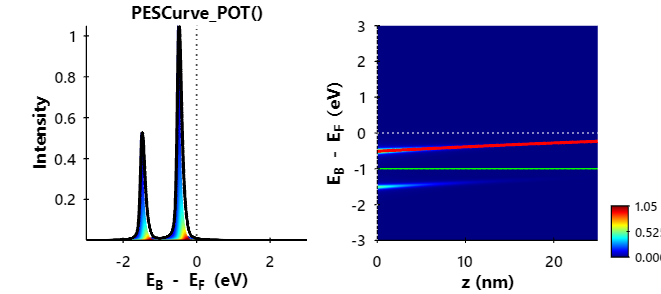

% 1 - Defining the input parameters
xdat = linspace(-3.0, 3.0, 5e3);
TYPE    = "sGLA";   % type of curve to use for fitting. Default: "sGLA" ("pGLA", "sGL", "pGL", "G", "L", "DS")
BE      =  -1.0;    % scalar of the binding energy of PE curve.
INT     =  1.05;    % scalar of the peak intensity of PE curve.
FWHM    =  0.1;     % scalar of the FWHM of the PE curve.
MR      =  0.5;     % scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
LSE     = -1.0;     % scalar of the binding energy of spin-orbit split PE curve.
LSI     =  0.5;     % scalar of the branching ratio of spin-orbit split PE curve.
LSW     =  0.0;     % scalar of the additional lorentzian width of spin-orbit split PE curve.
ASY     =  0.0;     % scalar of the PE curve asymmetry parameter (usually for metallic systems).
MFP     =  5.0;     % scalar of the mean-free path of the emitted photoelectrons (either from optical, TPP-2M or fits) [nm]
ZPOT    = linspace(0, 25, 400);                           % 1xN array of the z-domain (depth) of the potential profile [eV]
EPOT    = 1./(1 + exp(-ZPOT*0.05)) - 0.01;      % 1xN array of the potential energy relative to the Fermi-level [eV]
% 2 - Calculating the lineshape
[ydat, PES_int]     = PESCurve_POT(xdat, TYPE, BE, INT, FWHM, MR, LSE, LSI, LSW, ASY, MFP, ZPOT, EPOT, 1);

# **Symmetric Curves**

xdat = linspace(-3, 3, 1e4);

## (1) Gaussian Lineshape

help Gauss;

  ydat = Gauss(xdat, x0, peak, fwhm)
    Function that evaluates a Gaussian curve after defining its position,
    full-width at half-maximum (FWHM) and amplitude.
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:       N×1 column vector of the input domain (binding energy for PES).
    -   x0:         scalar of the peak position along the x-axis of the Gaussian.
    -   peak:       scalar of the peak height of the Gaussian.
    -   fwhm:       scalar of the full-width at half-maximum (FWHM) of the Gaussian.
 
    OUT:
    -   ydat:       N×1 column vector of the intensity range (intensity for PES).



% 1 - Defining the input parameters
x0          = 0;            % scalar of the peak position along the x-axis of the Gaussian.
peak        = 1.38;            % scalar of the peak beneath the Gaussian.
fwhm        = 0.5:0.1:1;    % scalar of the full-width at half-maximum (FWHM) of the Gaussian.
% 2 - Calculating the lineshape
lgnd = {};
for i = 1:length(fwhm)
    int_gauss{i}    = Gauss(xdat, x0, peak, fwhm(i));
    lgnd{i}         = "GauW = " + string(fwhm(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on; 
col_gauss = jet(length(fwhm) + 1);
for i = 1:length(fwhm)
    plot(xdat, int_gauss{i}, 'k-', 'color', col_gauss(i,:), 'linewidth', 2);
    % -- Verifying the peak peak
    cpeak   = max(int_gauss{i}(:));
    % -- Verifying the FWHM
    halfMax = 0.5*max(int_gauss{i}(:));                      % Find the half max value
    index1  = find(int_gauss{i}(:) >= halfMax, 1, 'first');  % Find where the data first drops below half the max
    index2  = find(int_gauss{i}(:) >= halfMax, 1, 'last');   % Find where the data last rises above half the max
    cfwhm   = xdat(index2) - xdat(index1);                  % Calculated FWHM
    sprintf("FWHM = %.2f, peak = %.2f", cfwhm, cpeak)
end

ans = "FWHM = 0.50, peak = 1.38"

ans = "FWHM = 0.60, peak = 1.38"

ans = "FWHM = 0.70, peak = 1.38"

ans = "FWHM = 0.80, peak = 1.38"

ans = "FWHM = 0.90, peak = 1.38"

ans = "FWHM = 1.00, peak = 1.38"

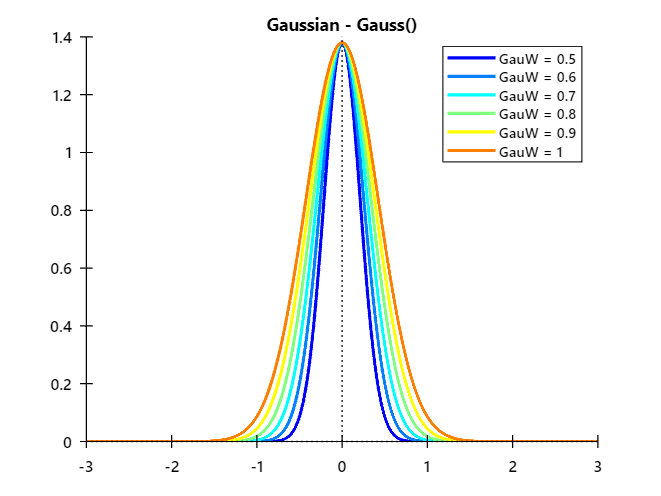

gca_props(); legend(lgnd, 'location', 'best', 'fontsize', 9); title('Gaussian - Gauss()');

## (2) Lorentzian Lineshape

help Lorentzian;

  ydat = Lorentzian(xdat, x0, peak, fwhm)
    Function that evaluates a Lorentzian curve after defining its position,
    full-width at half-maximum (FWHM) and amplitude.
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:       N×1 column vector of the input domain (binding energy for PES).
    -   x0:         scalar of the peak position along the x-axis of the Lorentzian.
    -   peak:       scalar of the peak height of the Lorentzian.
    -   fwhm:       scalar of the full-width at half-maximum (FWHM) of the Lorentzian.
 
    OUT:
    -   ydat:       N×1 column vector of the intensity range (intensity for PES).



% 1 - Defining the input parameters
x0          = 0;            % scalar of the peak position along the x-axis of the Lorentzian.
peak        = 0.93;            % scalar of the peak beneath the Lorentzian.
fwhm        = 0.5:0.1:1;    % scalar of the full-width at half-maximum (FWHM) of the Lorentzian.
% 2 - Calculating the lineshape
lgnd = {};
for i = 1:length(fwhm)
    int_lorentz{i}    = Lorentzian(xdat, x0, peak, fwhm(i));
    lgnd{i}           = "LorW = " + string(fwhm(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on; 
col_gauss = jet(length(fwhm) + 1);
for i = 1:length(fwhm)
    plot(xdat, int_lorentz{i}, 'k-', 'color', col_gauss(i,:), 'linewidth', 2);
    % -- Verifying the peak peak
    cpeak   = max(int_lorentz{i}(:));
    % -- Verifying the FWHM
    halfMax = 0.5*max(int_lorentz{i}(:));                      % Find the half max value
    index1  = find(int_lorentz{i}(:) >= halfMax, 1, 'first');  % Find where the data first drops below half the max
    index2  = find(int_lorentz{i}(:) >= halfMax, 1, 'last');   % Find where the data last rises above half the max
    cfwhm   = xdat(index2) - xdat(index1);                     % Calculated FWHM
    sprintf("FWHM = %.2f, peak = %.2f", cfwhm, cpeak)
end

ans = "FWHM = 0.50, peak = 0.93"

ans = "FWHM = 0.60, peak = 0.93"

ans = "FWHM = 0.70, peak = 0.93"

ans = "FWHM = 0.80, peak = 0.93"

ans = "FWHM = 0.90, peak = 0.93"

ans = "FWHM = 1.00, peak = 0.93"

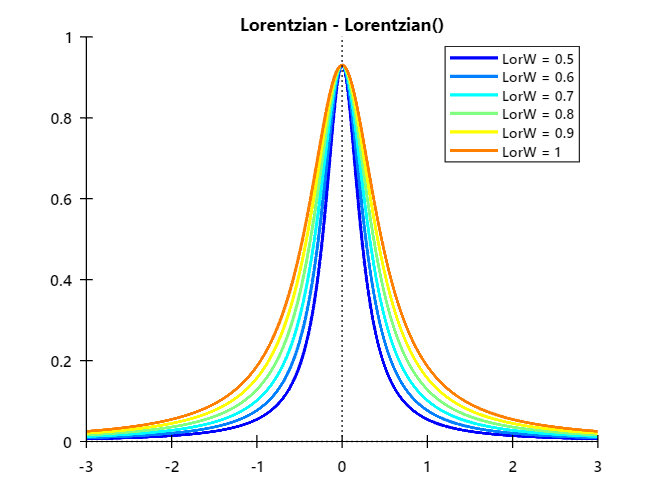

gca_props(); legend(lgnd, 'location', 'best', 'fontsize', 9); title('Lorentzian - Lorentzian()');

## (3) Pseudo-Voigt Lineshape - Gaussian / Lorentzian Sum

help sGL;

  ydat = sGL(xdat, x0, peak, fwhm, mr)
    Function that evaluates a pseudo-Voigt curve by expressing the curve
    profile as a SUM of Gaussian/Lorentzian curve types.
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:       N×1 column vector of the input domain (binding energy for PES).
    -   x0:         scalar of the peak position along the x-axis of the Voigt.
    -   peak:       scalar of the peak height of the Voigt.
    -   fwhm:       scalar of the full-width at half-maximum (FWHM) of the Voigt.
    -   mr:         mixing ratio; 0 for pure Gaussian, 1 is for pure Lorentzian
 
    OUT:
    -   ydat:       N×1 column vector of the intensity range (intensity for PES).



% 1 - Defining the input parameters
x0          = 0;            % scalar of the peak position along the x-axis of the Lorentzian.
peak        = 1.0;          % scalar of the peak beneath the Lorentzian.
fwhm        = 0.75;         % scalar of the full-width at half-maximum (FWHM) of the Lorentzian.
mr          = 0.1:0.1:1;    % scalar of the mixing ratio; 0 for pure Gaussian, 1 is for pure Lorentzian.
% 2 - Calculating the lineshape
lgnd = {};
for i = 1:length(mr)
    int_sGL{i}    = sGL(xdat, x0, peak, fwhm, mr(i));
    lgnd{i}         = "sGL-MR = " + string(mr(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on; 
col_gauss = jet(length(mr) + 1);
for i = 1:length(mr)
    plot(xdat, int_sGL{i}, 'k-', 'color', col_gauss(i,:), 'linewidth', 2);
    % -- Verifying the peak peak
    cpeak   = max(int_sGL{i}(:));
    % -- Verifying the FWHM
    halfMax = 0.5*max(int_sGL{i}(:));                      % Find the half max value
    index1  = find(int_sGL{i}(:) >= halfMax, 1, 'first');  % Find where the data first drops below half the max
    index2  = find(int_sGL{i}(:) >= halfMax, 1, 'last');   % Find where the data last rises above half the max
    cfwhm   = xdat(index2) - xdat(index1);                   % Calculated FWHM
    sprintf("FWHM = %.2f, peak = %.2f", cfwhm, cpeak)
end

ans = "FWHM = 0.75, peak = 1.00"

ans = "FWHM = 0.75, peak = 1.00"

ans = "FWHM = 0.75, peak = 1.00"

ans = "FWHM = 0.75, peak = 1.00"

ans = "FWHM = 0.75, peak = 1.00"

ans = "FWHM = 0.75, peak = 1.00"

ans = "FWHM = 0.75, peak = 1.00"

ans = "FWHM = 0.75, peak = 1.00"

ans = "FWHM = 0.75, peak = 1.00"

ans = "FWHM = 0.75, peak = 1.00"

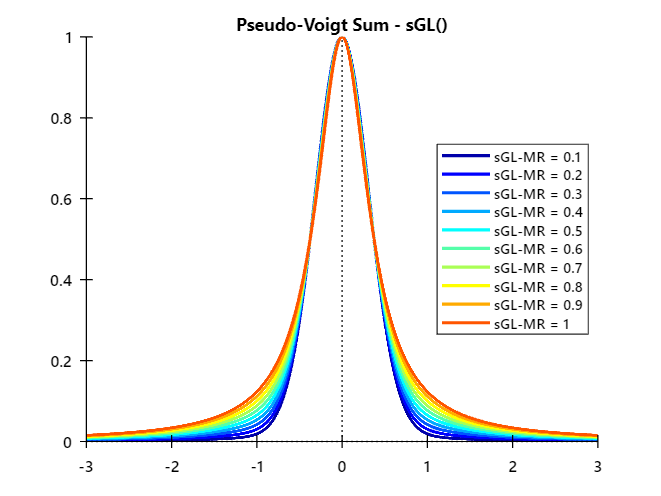

gca_props(); legend(lgnd, 'location', 'best', 'fontsize', 9); title('Pseudo-Voigt Sum - sGL()');

## (4) Pseudo-Voigt Lineshape - Gaussian / Lorentzian Product

help pGL;

  ydat = pGL(xdat, x0, peak, fwhm, mr)
    Function that evaluates a pseudo-Voigt curve by expressing the curve
    profile as a PRODUCT of Gaussian/Lorentzian curve types.
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:       N×1 column vector of the input domain (binding energy for PES).
    -   x0:         scalar of the peak position along the x-axis of the Voigt.
    -   peak:       scalar of the peak height of the Voigt.
    -   fwhm:       scalar of the full-width at half-maximum (FWHM) of the Voigt.
    -   mr:         mixing ratio; 0 for pure Gaussian, 1 is for pure Lorentzian
 
    OUT:
    -   ydat:       N×1 column vector of the intensity range (intensity for PES).



% 1 - Defining the input parameters
x0          = 0;            % scalar of the peak position along the x-axis of the Lorentzian.
peak        = 1.0;          % scalar of the peak beneath the Lorentzian.
fwhm        = 0.75;         % scalar of the full-width at half-maximum (FWHM) of the Lorentzian.
mr          = 0.1:0.1:1;    % scalar of the mixing ratio; 0 for pure Gaussian, 1 is for pure Lorentzian.
% 2 - Calculating the lineshape
lgnd = {};
for i = 1:length(mr)
    int_pGL{i}    = pGL(xdat, x0, peak, fwhm, mr(i));
    lgnd{i}       = "pGL-MR = " + string(mr(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on; 
col_gauss = jet(length(mr) + 1);
for i = 1:length(mr)
    plot(xdat, int_pGL{i}, 'k-', 'color', col_gauss(i,:), 'linewidth', 2);
    % -- Verifying the peak peak
    cpeak   = max(int_pGL{i}(:));
    % -- Verifying the FWHM
    halfMax = 0.5*max(int_pGL{i}(:));                      % Find the half max value
    index1  = find(int_pGL{i}(:) >= halfMax, 1, 'first');  % Find where the data first drops below half the max
    index2  = find(int_pGL{i}(:) >= halfMax, 1, 'last');   % Find where the data last rises above half the max
    cfwhm   = xdat(index2) - xdat(index1);                   % Calculated FWHM
    sprintf("FWHM = %.2f, peak = %.2f", cfwhm, cpeak)
end

ans = "FWHM = 0.74, peak = 1.00"

ans = "FWHM = 0.73, peak = 1.00"

ans = "FWHM = 0.72, peak = 1.00"

ans = "FWHM = 0.72, peak = 1.00"

ans = "FWHM = 0.72, peak = 1.00"

ans = "FWHM = 0.72, peak = 1.00"

ans = "FWHM = 0.72, peak = 1.00"

ans = "FWHM = 0.73, peak = 1.00"

ans = "FWHM = 0.74, peak = 1.00"

ans = "FWHM = 0.75, peak = 1.00"

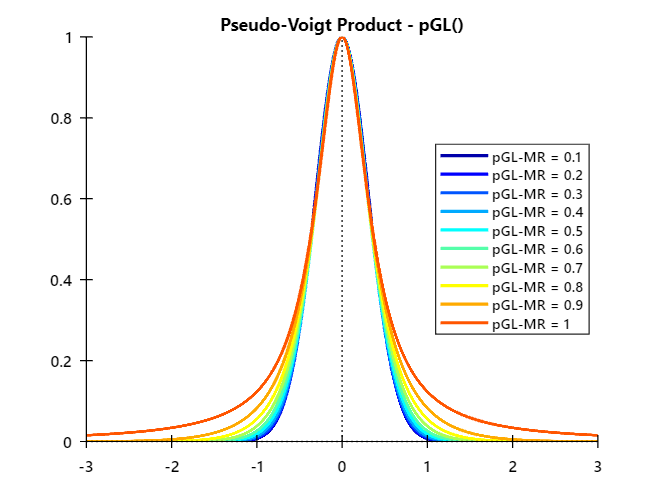

gca_props(); legend(lgnd, 'location', 'best', 'fontsize', 9); title('Pseudo-Voigt Product - pGL()');

# **Asymmetric Curves**

xdat = linspace(-3, 3, 1e4);

## (1) Doniach-Sunjic Lineshape

help DoniachSunjic;

  ydat = DoniachSunjic(xdat, x0, peak, fwhm, asym)
    Function that evaluates a Doniach-Sunjic curve after defining its position,
    full-width at half-maximum (FWHM), amplitude and asymmetry. The formula
    is used to characterise the asymmetry in the measured XPS of metallic
    systems. The problem with this function is that it lacks proper
    quantification, as F and E are both quantities that are related to the
    FWHM and peak position respectively, but not exactly equal to them. It
    is better to use Voigt lineshapes for fitting photoemission peaks.
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:       N×1 column vector of the input domain (binding energy for PES).
    -   x0:         scalar of the (approximate) peak position.
    -   peak:       scalar of the peak height.
    -   fwhm:       scalar of the (approximate) FWHM.
    -   asym:       asymmetry ratio; 0 for none, 1 is for maximum
 
    OUT:
    -   ydat:       N×1 column vector of the intens

% 1 - Defining the input parameters
x0          = 0;            % scalar of the peak position along the x-axis of the Lorentzian.
peak        = 1.0;          % scalar of the peak beneath the Lorentzian.
fwhm        = 0.15;         % scalar of the width parameter
asym        = 0.0:0.1:0.5;    % scalar of the asymmetry ratio; 0 for none, 1 is for maximum.
% 2 - Calculating the lineshape
lgnd = {};
for i = 1:length(asym)
    int_DS{i}    = DoniachSunjic(xdat, x0, peak, fwhm, asym(i));
    lgnd{i}         = "DS-asym = " + string(asym(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on; 
col_gauss = jet(length(asym) + 1);
for i = 1:length(asym)
    plot(xdat, int_DS{i}, 'k-', 'color', col_gauss(i,:), 'linewidth', 2);
    % -- Verifying the peak peak
    cpeak   = max(int_DS{i}(:));
    % -- Verifying the FWHM
    halfMax = 0.5*max(int_DS{i}(:));                      % Find the half max value
    index1  = find(int_DS{i}(:) >= halfMax, 1, 'first');  % Find where the data first drops below half the max
    index2  = find(int_DS{i}(:) >= halfMax, 1, 'last');   % Find where the data last rises above half the max
    cfwhm   = xdat(index2) - xdat(index1);                   % Calculated FWHM
    sprintf("FWHM = %.2f, peak = %.2f", cfwhm, cpeak)
end

ans = "FWHM = 0.30, peak = 1.00"

ans = "FWHM = 0.34, peak = 1.00"

ans = "FWHM = 0.40, peak = 1.00"

ans = "FWHM = 0.50, peak = 1.00"

ans = "FWHM = 0.68, peak = 1.00"

ans = "FWHM = 1.02, peak = 1.00"

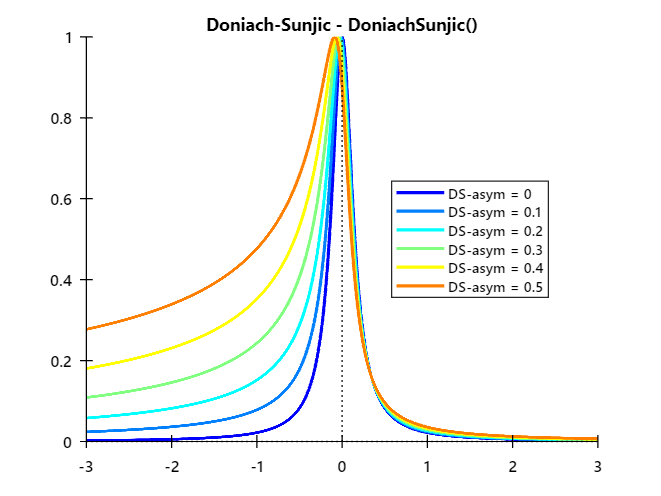

gca_props(); legend(lgnd, 'location', 'best', 'fontsize', 9); title('Doniach-Sunjic - DoniachSunjic()');

## (2) Asymmetric Exponential Blend (AEB) Function

help AEB;

  ydat = AEB(xdat, x0, asym)
    Function that evaluates an asymmetric exponential blend (AEB), that is 
    used to create the asymmetric Voigt-type lineshapes. The asymmetric profile
    obtained from the blend is: Y(x) = GL(x) + AEB(x) * (1 - GL(x)).
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:       N×1 column vector of the input domain (binding energy for PES).
    -   x0:         scalar of the position where the AEB will start.
    -   asym:       asymmetry ratio; 0 for none, 0->1 is for LHS asymmetry, -1->0 is for RHS asymmetry.
 
    OUT:
    -   ydat:       N×1 column vector of the intensity range (intensity for PES).



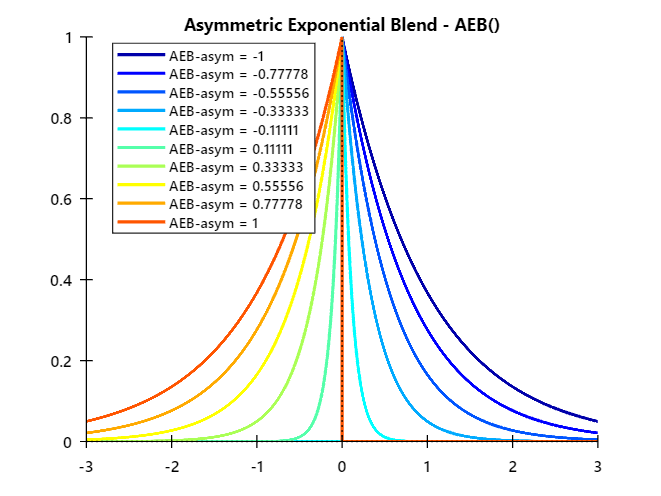

% 1 - Defining the input parameters
x0          = 0.;            % scalar of the peak position along the x-axis of the Lorentzian.
asym        = linspace(-1,1,10);            % scalar of the asymmetry ratio; 0 for none, 1 is for maximum.
% 2 - Calculating the lineshape
lgnd = {};
for i = 1:length(asym)
    int_AEB{i}    = AEB(xdat, x0, asym(i));
    lgnd{i}        = "AEB-asym = " + string(asym(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on; 
col_gauss = jet(length(asym) + 1);
for i = 1:length(asym)
    plot(xdat, int_AEB{i}, 'k-', 'color', col_gauss(i,:), 'linewidth', 2);
end
gca_props(); legend(lgnd, 'location', 'best', 'fontsize', 9); title('Asymmetric Exponential Blend - AEB()');

## (3) Asymmetric Pseudo-Voigt Lineshape - Gaussian / Lorentzian Sum

help sGLA;

  ydat = sGLA(xdat, x0, peak, fwhm, mr, asym)
    Function that evaluates a, asymmetric pseudo-Voigt curve by expressing 
    the curve profile as a SUM of Gaussian/Lorentzian curve types.
    The curve is modified here with the asymmetric, exponential blend, 
    where:  sGLA(x) = sGL(x) + AEB(x) * (1 - sGL(x)). 
    AEB(x) is determined from (AEB()).
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:       N×1 column vector of the input domain (binding energy for PES).
    -   x0:         scalar of the peak position along the x-axis of the Voigt.
    -   peak:       scalar of the peak height of the Voigt.
    -   fwhm:       scalar of the full-width at half-maximum (FWHM) of the Voigt.
    -   mr:         mixing ratio; 0 for pure Gaussian, 1 is for pure Lorentzian
    -   asym:       asymmetry ratio; 0 for none, 1 is for maximum
 
    OUT:
    -   ydat:       N×1 column vector of the intensity range (intensity for PES).



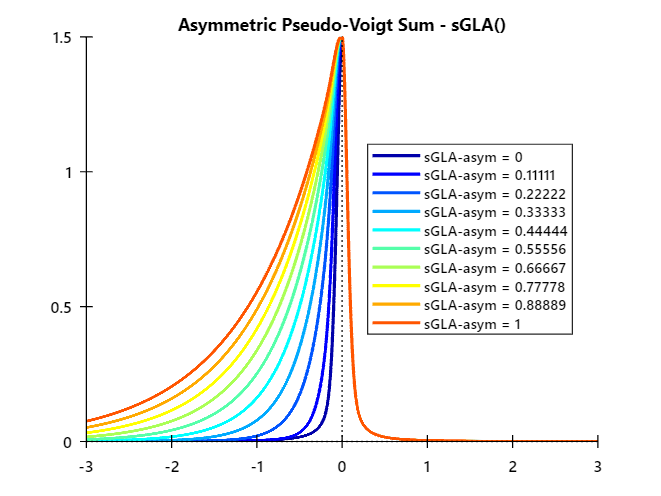

% 1 - Defining the input parameters
x0          = 0;            % scalar of the peak position along the x-axis of the Lorentzian.
peak        = 1.5;          % scalar of the peak beneath the Lorentzian.
fwhm        = 0.15;         % scalar of the full-width at half-maximum (FWHM) of the Lorentzian.
mr          = 0.5;          % scalar of the mixing ratio; 0 for pure Gaussian, 1 is for pure Lorentzian.
asym        = linspace(0,1,10);            % scalar of the asymmetry ratio; 0 for none, 1 is for maximum.
% 2 - Calculating the lineshape
lgnd = {};
for i = 1:length(asym)
    int_sGLA{i}    = sGLA(xdat, x0, peak, fwhm, mr, asym(i));
    lgnd{i}        = "sGLA-asym = " + string(asym(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on; 
col_gauss = jet(length(asym) + 1);
for i = 1:length(asym)
    plot(xdat, int_sGLA{i}, 'k-', 'color', col_gauss(i,:), 'linewidth', 2);
end
gca_props(); legend(lgnd, 'location', 'best', 'fontsize', 9); title('Asymmetric Pseudo-Voigt Sum - sGLA()');

## (4) Asymmetric Pseudo-Voigt Lineshape - Gaussian / Lorentzian Product

help pGLA;

  ydat = pGLA(xdat, x0, peak, fwhm, mr, asym)
    Function that evaluates a, asymmetric pseudo-Voigt curve by expressing 
    the curve profile as a PRODUCT of Gaussian/Lorentzian curve types.
    The curve is modified here with the asymmetric, exponential blend, 
    where:  pGLA(x) = pGL(x) + AEB(x) * (1 - pGL(x)). 
    AEB(x) is determined from (AEB()).
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:       N×1 column vector of the input domain (binding energy for PES).
    -   x0:         scalar of the peak position along the x-axis of the Voigt.
    -   peak:       scalar of the peak height of the Voigt.
    -   fwhm:       scalar of the full-width at half-maximum (FWHM) of the Voigt.
    -   mr:         mixing ratio; 0 for pure Gaussian, 1 is for pure Lorentzian
    -   asym:       asymmetry ratio; 0 for none, 1 is for maximum
 
    OUT:
    -   ydat:       N×1 column vector of the intensity range (intensity for PES).



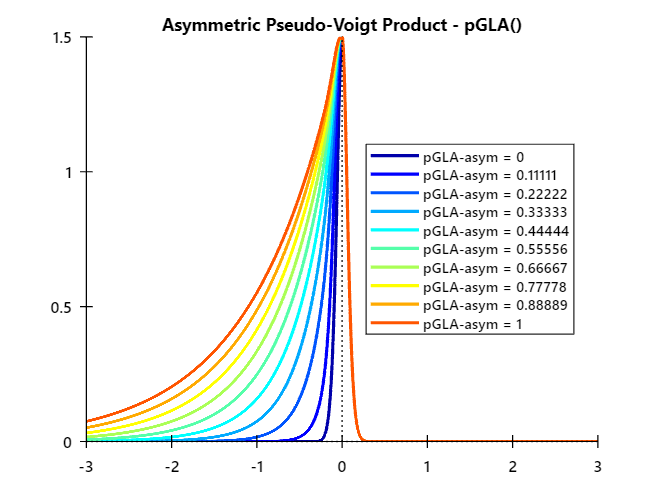

% 1 - Defining the input parameters
x0          = 0;            % scalar of the peak position along the x-axis of the Lorentzian.
peak        = 1.5;          % scalar of the peak beneath the Lorentzian.
fwhm        = 0.15;         % scalar of the full-width at half-maximum (FWHM) of the Lorentzian.
mr          = 0.5;          % scalar of the mixing ratio; 0 for pure Gaussian, 1 is for pure Lorentzian.
asym        = linspace(0,1,10);            % scalar of the asymmetry ratio; 0 for none, 1 is for maximum.
% 2 - Calculating the lineshape
lgnd = {};
for i = 1:length(asym)
    int_pGLA{i}    = pGLA(xdat, x0, peak, fwhm, mr, asym(i));
    lgnd{i}        = "pGLA-asym = " + string(asym(i));
    % -- Extracting the exponential blend function
    int_AEB{i}      = AEB(xdat, x0, asym(i));
    int_AEB{i}      = int_AEB{i} .* (max(int_pGLA{i}(:)) - int_pGLA{i});
end
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on; 
col_gauss = jet(length(asym) + 1);
for i = 1:length(asym)
    plot(xdat, int_pGLA{i}, 'k-', 'color', col_gauss(i,:), 'linewidth', 2);
%     h = plot(xdat, int_AEB{i}, 'k--', 'color', col_gauss(i,:), 'linewidth', 1);
%     h.Annotation.LegendInformation.IconDisplayStyle = 'off';
end
gca_props(); legend(lgnd, 'location', 'best', 'fontsize', 9); title('Asymmetric Pseudo-Voigt Product - pGLA()');

## (5) Asymmetric Pseudo-Voigt Lineshape - Gaussian / Lorentzian Product - Convolved with FDD function

help pGLA_FDD;

  ydat = pGLA_FDD(xdat, x0, peak, fwhm, mr, asym, fdd_ef, fdd_T, fdd_fwhm)
    Function that evaluates an asymmetric pseudo-Voigt curve with the
    pGLA() function, after which it is multiplied by the Fermi-Dirac
    Distribution FDDG(). These curve shapes are used for fitting EDCs near
    the Fermi-edge, where the curve profiles may be chopped slightly due to
    the close proximity of the Fermi-edge.
 
    REQ. FUNCTIONS:
    -   pGLA()
    -   FDDG()
 
    IN:
    -   xdat:           N×1 column vector of the input domain (binding energy for PES).
    -   x0:             scalar of the peak position along the x-axis of the Voigt.
    -   peak:           scalar of the peak height of the Voigt.
    -   fwhm:           scalar of the full-width at half-maximum (FWHM) of the Voigt.
    -   mr:             mixing ratio; 0 for pure Gaussian, 1 is for pure Lorentzian
    -   asym:           asymmetry ratio; 0 for none, 1 is for maximum
    -   fdd_ef:         scalar of the 

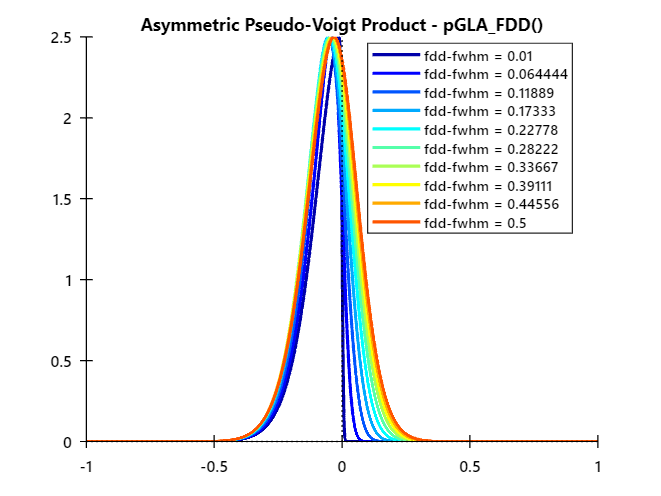

xdat = linspace(-1, 1, 1e4);
% 1 - Defining the input parameters
x0          = 0;            % scalar of the peak position along the x-axis of the Lorentzian.
peak        = 2.50;          % scalar of the peak beneath the Lorentzian.
fwhm        = 0.25;         % scalar of the full-width at half-maximum (FWHM) of the Lorentzian.
mr          = 0.5;          % scalar of the mixing ratio; 0 for pure Gaussian, 1 is for pure Lorentzian.
asym        = 0.0;          % scalar of the asymmetry ratio; 0 for none, 1 is for maximum.
fdd_ef      = 0.0;            % scalar of the location of the Fermi-level
fdd_T       = 12;           % scalar of the temperature of the system
fdd_fwhm    = linspace(0.01, 0.5, 10);         % scalar of the Gaussian FWHM to be convolved

% 2 - Calculating the lineshape
lgnd = {};
for i = 1:length(fdd_fwhm)
    int_pGLA_FDD{i}     = pGLA_FDD(xdat, x0, peak, fwhm, mr, asym, fdd_ef, fdd_T, fdd_fwhm(i));
    lgnd{i}             = "fdd-fwhm = " + string(fdd_fwhm(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on; 
col_gauss = jet(length(fdd_fwhm) + 1);
for i = 1:length(fdd_fwhm)
    plot(xdat, int_pGLA_FDD{i}, 'k-', 'color', col_gauss(i,:), 'linewidth', 2);
end
gca_props(); legend(lgnd, 'location', 'best', 'fontsize', 9); title('Asymmetric Pseudo-Voigt Product - pGLA_FDD()', 'interpreter', 'none');

# **Fermi-Dirac Distributions**

xdat = linspace(-1, 1, 1e4);

## (1) Pure FDD function

help FDD;

  ydat = FDD(xdat, fdd_ef, fdd_T)
    This function determines the Fermi-Dirac Distribution (FDD) given the 
    fermi-energy (fdd_ef) and temperature (fdd_T). This is the pure, theoretical
    FDD function.
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:       N×1 column vector of the input domain (binding energy for PES).
    -   fdd_ef:   	scalar of the Fermi-level position (eV).
    -   fdd_T:     	scalar of the temperature (K).
 
    OUT:
    -   ydat:       N×1 column vector of the intensity range (intensity for PES).



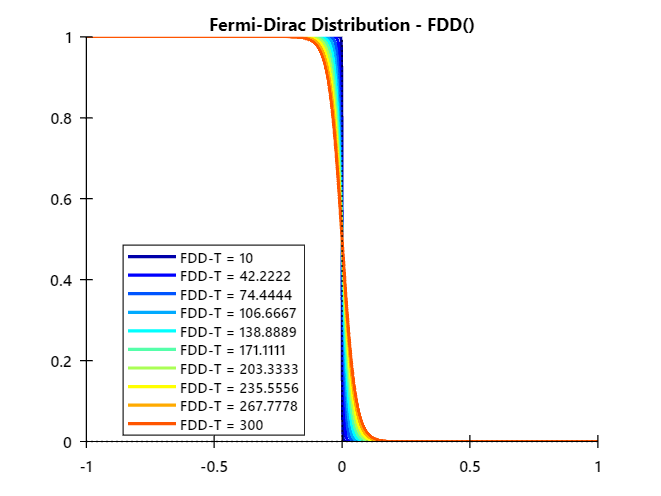

% 1 - Defining the input parameters
FDEF          = 0;                  % scalar of the location of the Fermi-level
FDT        = linspace(10, 300, 10); % scalar of the temperature of the system
% 2 - Calculating the lineshape
lgnd = {};
for i = 1:length(FDT)
    int_FDD{i}    = FDD(xdat, FDEF, FDT(i));
    lgnd{i}       = "FDD-T = " + string(FDT(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on; 
col_gauss = jet(length(FDT) + 1);
for i = 1:length(FDT)
    plot(xdat, int_FDD{i}, 'k-', 'color', col_gauss(i,:), 'linewidth', 2);
end
gca_props(); legend(lgnd, 'location', 'best', 'fontsize', 9); title('Fermi-Dirac Distribution - FDD()');

## (2) Gaussian broadened FDD function

help FDDG;

  ydat = FDDG(xdat, fdd_ef, fdd_T, fdd_fwhm)
    This function determines the Fermi-Dirac Distribution (FDD) given the 
    fermi-energy (fdd_ef) and temperature (fdd_T). A convolution is then made with
    a Gaussian, with a well-defined full-width half-maximum (fdd_fwhm) to
    include the broadening introducted by the beamline+analyzer resolution.
 
    REQ. FUNCTIONS:
    -   FDD()
    -   Gauss()
 
    IN:
    -   xdat:       N×1 column vector of the input domain (binding energy for PES).
    -   fdd_ef:   	scalar of the Fermi-level position (eV).
    -   fdd_T:     	scalar of the temperature (K).
    -   fdd_fwhm: 	scalar of the full-width at half-maximum (FWHM) of the Gaussian broadening term (eV).
 
    OUT:
    -   ydat:       N×1 column vector of the intensity range (intensity for PES).



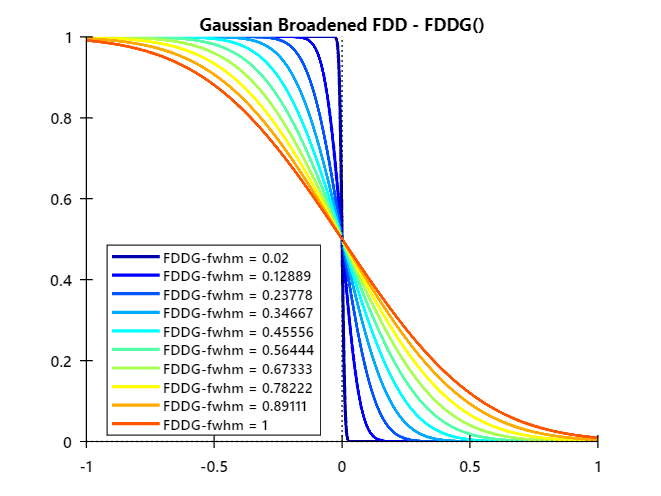

% 1 - Defining the input parameters
FDEF        = 0;            % scalar of the location of the Fermi-level
FDT         = 12;           % scalar of the temperature of the system
FDW         = linspace(0.02, 1.0, 10);         % scalar of the Gaussian FWHM to be convolved
% 2 - Calculating the lineshape
lgnd = {};
for i = 1:length(FDW)
    int_FDDG{i}    = FDDG(xdat, FDEF, FDT, FDW(i));
    lgnd{i}       = "FDDG-fwhm = " + string(FDW(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on; 
col_gauss = jet(length(FDW) + 1);
for i = 1:length(FDW)
    plot(xdat, int_FDDG{i}, 'k-', 'color', col_gauss(i,:), 'linewidth', 2);
end
gca_props(); legend(lgnd, 'location', 'best', 'fontsize', 9); title('Gaussian Broadened FDD - FDDG()');

## (3) Gaussian broadened FDD function with a linear background multiplied

help FDDGpL;

  ydat = FDDGpL(xdat, fdd_ef, fdd_T, fdd_fwhm, lin_grad, lin_inter, const_bgrnd)
    This function determines the Fermi-Dirac Distribution (FDD) given the 
    fermi-energy (fdd_ef) and temperature (fdd_T). A convolution is then made with
    a Gaussian, with a well-defined full-width half-maximum (fdd_fwhm) to
    include the broadening introducted by the beamline+analyzer resolution.
    Furthermore, a linear background is MULTIPLIED to accound for any
    linear distortion of the Fermi-edge, defined by the gradient and intercept.
    An additional constant background is also added (const_bgrnd).
 
    REQ. FUNCTIONS: 
    -   FDDG()
 
    IN:
    -   xdat:           N×1 column vector of the input domain (binding energy for PES).
    -   fdd_ef:         scalar of the Fermi-level position (eV).
    -   fdd_T:          scalar of the temperature (K).
    -   fdd_fwhm:       scalar of the full-width at half-maximum (FWHM) of the Gaussian broadening term (eV).
    -   lin

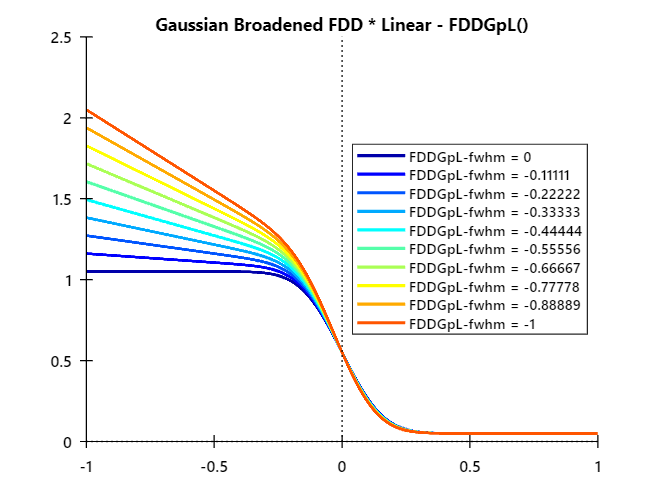

% 1 - Defining the input parameters
FDEF    = 0.0;          % scalar of the location of the Fermi-level
FDT     = 12;           % scalar of the temperature of the system
FDW     = 0.30;         % scalar of the Gaussian FWHM to be convolved
BGR     = -linspace(0, 1, 10);% scalar of the gradient of the linear background.
BIN     = 1.;           % scalar of the y-intercept of the linear background.
BCO     = 0.05;         % scalar of the constant background y-offset value.
% 2 - Calculating the lineshape
lgnd = {};
for i = 1:length(BGR)
    int_FDDGpL{i}    = FDDGpL(xdat, FDEF, FDT, FDW, BGR(i), BIN, BCO);
    lgnd{i}       = "FDDGpL-fwhm = " + string(BGR(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on; 
col_gauss = jet(length(BGR) + 1);
for i = 1:length(BGR)
    plot(xdat, int_FDDGpL{i}, 'k-', 'color', col_gauss(i,:), 'linewidth', 2);
end
gca_props(); legend(lgnd, 'location', 'best', 'fontsize', 9); title('Gaussian Broadened FDD * Linear - FDDGpL()');

## (4) Gaussian broadened FDD function with a linear background added

help FDDGsL;

  ydat = FDDGsL(xdat, fdd_ef, fdd_T, fdd_fwhm, lin_grad, lin_inter, const_bgrnd)
    This function determines the Fermi-Dirac Distribution (FDD) given the 
    fermi-energy (fdd_ef) and temperature (fdd_T). A convolution is then made with
    a Gaussian, with a well-defined full-width half-maximum (fdd_fwhm) to
    include the broadening introducted by the beamline+analyzer resolution.
    Furthermore, a linear background is SUMMED to accound for any
    linear distortion of the Fermi-edge, defined by the gradient and intercept.
    An additional constant background is also added (const_bgrnd).
 
    REQ. FUNCTIONS: 
    -   FDDG()
 
    IN:
    -   xdat:           N×1 column vector of the input domain (binding energy for PES).
    -   fdd_ef:         scalar of the Fermi-level position (eV).
    -   fdd_T:          scalar of the temperature (K).
    -   fdd_fwhm:       scalar of the full-width at half-maximum (FWHM) of the Gaussian broadening term (eV).
    -   lin_gra

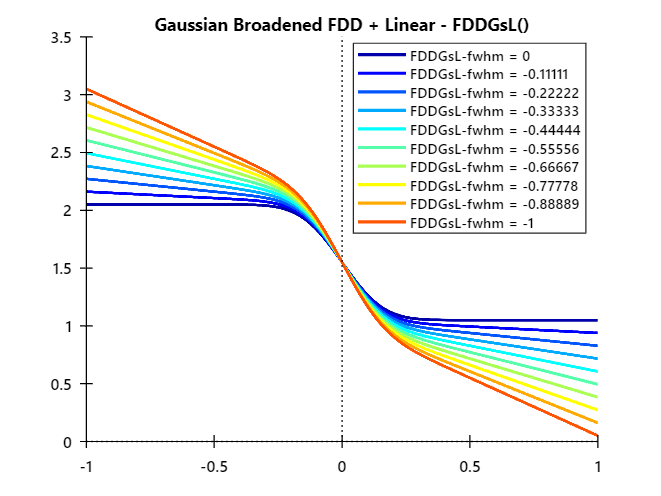

% 1 - Defining the input parameters
FDEF      = 0.0;            % scalar of the location of the Fermi-level
FDT    = 12;           % scalar of the temperature of the system
FDW   = 0.30;         % scalar of the Gaussian FWHM to be convolved
BGR    = -linspace(0, 1, 10);
BIN    = 1.;
BCO   = 0.05;
% 2 - Calculating the lineshape
lgnd = {};
for i = 1:length(BGR)
    int_FDDGsL{i}    = FDDGsL(xdat, FDEF, FDT, FDW, BGR(i), BIN, BCO);
    lgnd{i}       = "FDDGsL-fwhm = " + string(BGR(i));
end
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); hold on; 
col_gauss = jet(length(BGR) + 1);
for i = 1:length(BGR)
    plot(xdat, int_FDDGsL{i}, 'k-', 'color', col_gauss(i,:), 'linewidth', 2);
end
gca_props(); legend(lgnd, 'location', 'best', 'fontsize', 9); title('Gaussian Broadened FDD + Linear - FDDGsL()');

# **APPENDIX : A LIST OF USEFUL MISCELLANEOUS FUNCTIONS**

## Appendix I - Extracting peak parameters

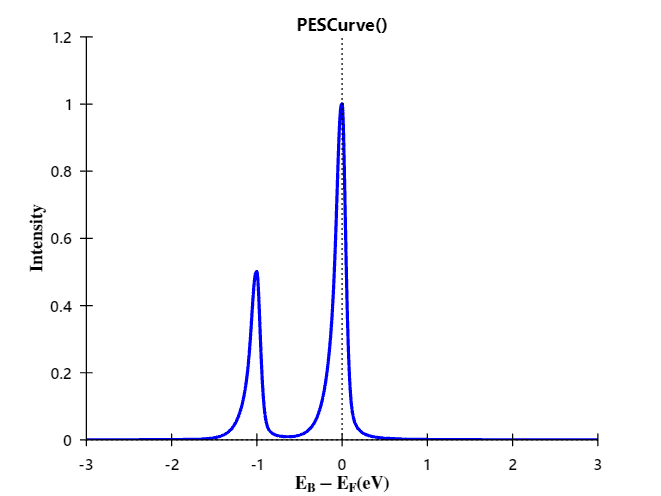

% 1 - Defining a curve to be used
xdat = linspace(-3, 3, 1e3);
TYPE    = "sGLA";   % type of curve to use for fitting. Default: "sGLA" ("pGLA", "sGL", "pGL", "G", "L", "DS")
BE      = 0.0;      % scalar of the binding energy of PE curve.
INT     = 1.0;      % scalar of the peak intensity of PE curve.
FDW    =  0.1;     % scalar of the FWHM of the PE curve.
MR      =  0.5;     % scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
LSE     = -1.0;     % scalar of the binding energy of spin-orbit split PE curve.
LSI     =  0.5;     % calar of the branching ratio of spin-orbit split PE curve.
LSW     =  0.0;     % scalar of the additional lorentzian width of spin-orbit split PE curve.
ASY     =  0.1;     % scalar of the PE curve asymmetry parameter (usually for metallic systems).
% 2 - Calculating the lineshape
ydat    = PESCurve(xdat, TYPE, BE, INT, FDW, MR, LSE, LSI, LSW, ASY);
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); plot(xdat, ydat, 'b-', 'linewidth', 2);
gca_props(); title('PESCurve()'); 
xlabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');
ylabel('$$ \bf  Intensity $$', 'Interpreter', 'latex');

  [xVal, yVal] = find_peak_loc(xdat, ydat, xWin, type, plot_results)
    This function is used to determine both the maximum value and position of
    a data set using a range of different methods; spline interpolation or
    curve fitting a gaussian / voigt function. 
 
    IN:
    -   xdat:           [N×1] column vector of the input domain.
    -   ydat:           [N×1] column vector of the output range.
    -   xWin:           [N×2] array that contains the x-windows where N peaks are expected to be found.
    -   type:           string of the type of method to use. Default: "spline" ("none","spline","gaco1","G","L","sGL","pGL","sGLA","pGLA").
    -   plot_result:    if 1, will plot figure summary, otherwise it wont.
 
    OUT:
    -   xVal:           scalar or [N×1] column vector of the maxima x-values.
    -   yVal:           scalar or [N×1] column vector of the maxima y-values.



ans = 5

ans = 7

1) x = -0.01, y = 0.99 
2) x = -1.01, y = 0.49 


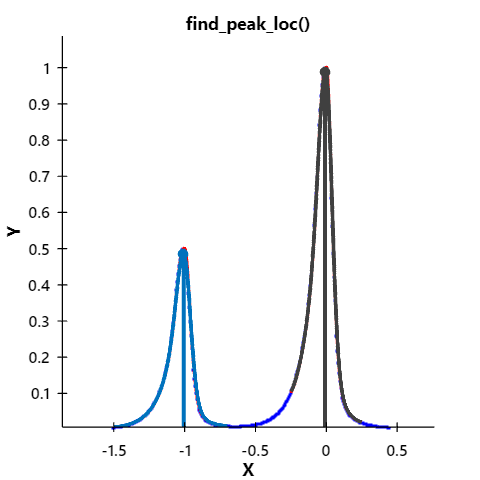

% 4 - Finding the peak position of the curve
help find_peak_loc; [xval, yval] = find_peak_loc(xdat, ydat, [-0.25, 0.25; -1.5, -0.7], "gaco1", 1);

  [fwhm, fwhmLocs] = find_peak_fwhm(xdat, ydat, xWin, type, plot_result)
    This function is used to determine both the fwhm of a data set using 
    a range of different methods; spline interpolation or curve fitting a 
    gaussian / voigt function. 
 
    REQ. FUNCTIONS: (none)
 
    IN:
    -   xdat:           [N×1] column vector of the input domain.
    -   ydat:           [N×1] column vector of the output range.
    -   xWin:           [N×2] array that contains the x-windows where N peaks are expected to be found.
    -   type:           string of the type of method to use. Default: "spline" ("none","spline","gaco1","G","L","sGL","pGL","sGLA","pGLA").
    -   plot_result:    if 1, will plot figure summary, otherwise it wont.
 
    OUT:
    -   fwhm:           scalar or [N×1] column vector of the fwhm of each peak defined.
    -   fwhmLocs:   	[2N×2] column vector of the fwhm positions.

1) x = 0.00, y = 1.00, fwhm = 0.14 
2) x = -1.00, y = 0.50, fwhm = 0.14 


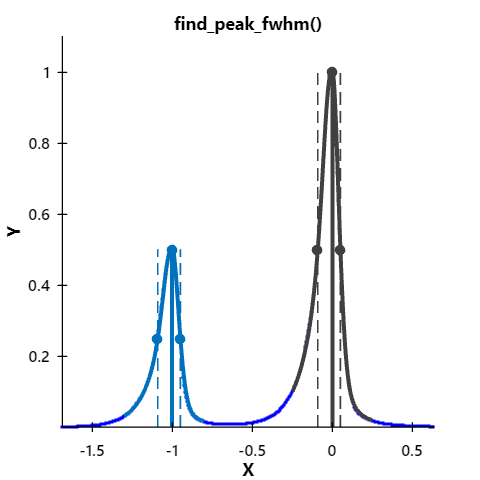

% 5 - Finding the peak fwhm of the curve
help find_peak_fwhm; [fwhm, fwhmLocs] = find_peak_fwhm(xdat, ydat, [-0.25, 0.25; -1.3, -0.8], "spline", 1);

## Appendix II - Fitting the Fermi-Dirac Distribution to determine Fermi-edge

help fdd2fit_solver

  [fitStr, Ef] = fdd2fit_solver(Angle, Energy, Data, AngleWin, EnergyWin, fddType, iparams, solve_type, plot_result)
    Function that runs an optimisation algorithm to solve for the best fit
    to a Fermi-Dirac Distribution. The FDD function can be chosen for
    optimal fitting to the data.
    
    REQ. FUNCTIONS: none
    
    IN:
    -   Angle:              [1×nAngle] row vector of angles.
    -   Energy:             [nEnergyx1] column vector of energy.
    -   Data:               [nEnergy x nAngle] data array.
    -   AngleWin:           1x2 vector of [minAngle, maxAngle] over which the fit is performed. Default: 95% of the full Angle window.
    -   EnergyWin:          1x2 vector of [minEnergy, maxEnergy] over which the fit is performed. Default: 95% of the full Energy window.
    -   fddType:            string of the type of FDD curve to use for fitting. Default: "FDDGsL" ("FDD", "FDDG", "FDDGpL", "FDDGsL")
    -   iparams:            3 cells {x0}{lb}{ub} with


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


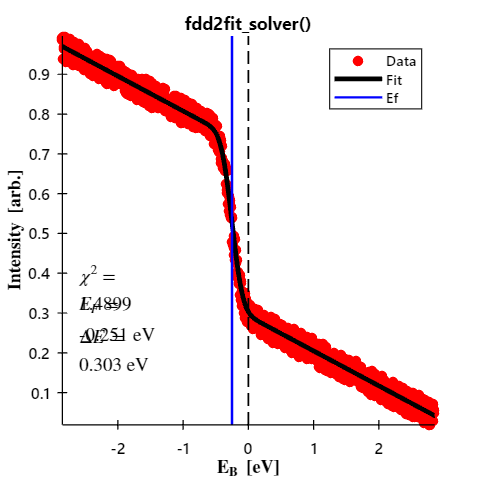

Ef = -0.2514

fitStr = struct with fields:
    solve_type: "lsqcurvefit"
       fddType: "FDDGsL"
       iparams: {[0 12 0.3000 0 0 0.5827 1]  [-2.8500 12 0 -5 -3 -1.7678 0]  [2.8500 12 2 0 3 1.7678 1.7678]}
      AngleWin: []
     EnergyWin: [-2.8500 2.8500]
          xdat: [1000×1 double]
          ydat: [1000×1 double]
             X: [950×1 double]
             D: [950×1 double]
             M: [950×1 double]
             R: [950×1 double]
         CHISQ: 1.4899
        MINFUN: 1.4899
           DoF: 6
            XX: [1000×1 double]
            YY: [1000×1 double]
        params: [7×1 double]
            EF: -0.2514
          TEMP: 12
          FWHM: 0.3029
          GRAD: -0.2051
        OFFSET: 0.1269
         BGRND: 0.5568
         SCALE: 0.4275


Ef = -0.2514

% 1 - Arbitrary 1D Fermi Edge
xdat    = linspace(-3, 3, 1e3);
ydat    = FDDGsL(xdat, -0.25, 12, 0.3, -0.2, 0, 0.05) + 0.15*rand(size(xdat))';
[fitStr, Ef] = fdd2fit_solver([], xdat, ydat, [], [], "FDDGsL")

% 2 - ARPES 2D data of Fermi Edge
path_data   = 'D:\OneDrive\PCC_MS_Project\00_SLS_Software\ARPEScape\ARPEScape-v8.1.0\PESTools_PCC\Examples\Example_Data\ADRESS_data\';
file_names_ref      = {...
    '002_ARPES_HSCUT_EF.h5',...
    };
arpes_ref = cell(1,length(file_names_ref));
for i = 1:length(file_names_ref); arpes_ref{i} = load_adress_data(file_names_ref{i}, path_data); end

Loading ADRESS data...


for i = 1:length(arpes_ref); arpes_ref{i} = xcorr_scans(arpes_ref{i}); end

- Correlating scans
Scan = 2: Offset = 0
Scan = 3: Offset = 0
Scan = 4: Offset = 0
Scan = 5: Offset = 0
Scan = 6: Offset = 0
Scan = 7: Offset = 0
Scan = 8: Offset = 0
Scan = 9: Offset = 0


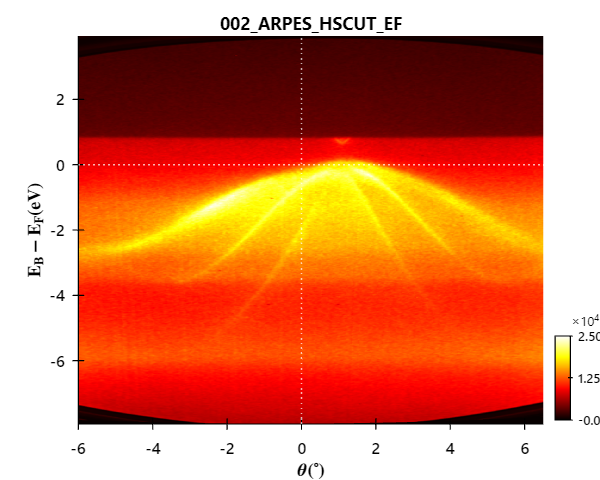

arpes_ref = arpes_ref{1};
view_arpes_data(arpes_ref);

- Angle integrating

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


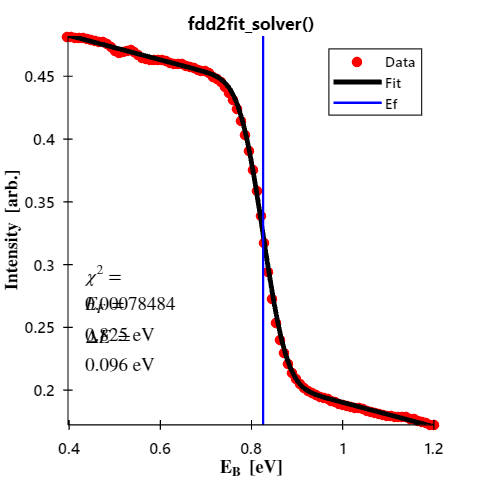

Ef = 0.8255

[fitStr, Ef] = fdd2fit_solver(arpes_ref.raw_tht, arpes_ref.raw_eb, arpes_ref.raw_data, [], [0.4, 1.2], "FDDGsL");